# Lesson II.1:  Families of Matrices

**Families of Matrices Already Seen.**   In this course, various families of matrices have been encountered including

- the $m\times n$ matrices with real entries (${\mathbb R}^{m\times n}$ ),

- the $m\times n$ matrices with complex entries (${\mathbb C}^{m\times n}$),

- the $n\times n$  real square matrices (${\mathbb R}^{n\times n}$)

- the $n\times n$  invertible matrices ($\text{GL}_n$),

- the $n\times n$  upper (or lower) triangular matrices,

- the $n\times n$  upper (or lower) unitriangular matrices,

- the $n\times n$  diagonal matrices,

- the $n\times n$  symmetric (or Hermitian symmetric) matrices,

- the $n\times n$  antisymmetric matrices,

- the $m\times n$ proto-row-echelon matrices,

- the $m\times n$ normalized row-echelon matrices,

- the $m\times n$ reduced row-echelon matrices,

- the elementary matrices (replacement, scaling and exchange).

Two aspects of matrix families are deserving of some attention:   ***inclusion relationships*** and ***closure properties***.   An inclusion relationship refers to a family of matrices being a subset of another family.   For example, the $n\times n$ diagonal matrices are a subset of the $n\times n$ upper triangular matrices, and the $m\times n$ reduced row-echelon matrices are a subset of the $m\times n$ normalized row-echelon matrices.   A closure property refers to operations on elements of a family that results in a member of the same family.   For example, the $n\times n$ diagonal matrices are closed under linear combination as a linear combination of $n\times n$ diagonal matrices is always an $n\times n$ diagonal matrix, and $\text{GL}_n$ is closed under matrix multiplication as $A\in\text{GL}_n$ and $B\in\text{GL}_n$ implies $AB\in\text{GL}_n$.

**The Gram matrix.**    We return to the Gram matrix that was introduced earlier.  For a general matrix $A\in{\mathbb C}^{m\times n}$ the ***Gram matrix ***is 

        (II.1.1a)        $A^HA$.

In the common event that $A\in{\mathbb R}^{m\times n}$ the Gram matrix can be defined with the ordinary transpose (rather than the Hermitian transpose):

        (II.1.1b)        $A^TA$.

Nonetheless, it is vital to remember that the Hermitian transpose is generally called for whenever $A$ has even one complex entry.   

The most obvious property of the Gram matrix of an $m\times n$ matrix is that it is an $n\times n$ matrix.     MATLAB provides some examples:

A=[1 2; 4 5; 7 8; 10 11]

A =      1     2
     4     5
     7     8
    10    11


A'*A

ans =    166   188
   188   214


A=[1 2 3]

A =      1     2     3


A'*A

ans =      1     2     3
     2     4     6
     3     6     9


A=[1;4;7]

A =      1
     4
     7


A'*A     % result will be 1x1

ans = 66

A=[1+i 1-i; 2+3*i 4-i]

A =    1.0000 + 1.0000i   1.0000 - 1.0000i
   2.0000 + 3.0000i   4.0000 - 1.0000i


A'*A

ans =   15.0000 + 0.0000i   5.0000 -16.0000i
   5.0000 +16.0000i  19.0000 + 0.0000i


Another easily verified property of the Gram matrix is that it is Hermitian symmetric:

        (II.1.2)        $(A^H A)^H=A^H {A^H}^H=A^H A$.

The entries of the Gram matrix of $A=\left[\matrix{{\bf a}_1 & {\bf a}_2&\cdots&{\bf a}_n}\right]$are the dot products of each column of $A$ with every other column of $A$ including itself:

        (II.1.3)        $A^HA=\left[\matrix{ 
{\bf a}_1^H{\bf a}_1 & {\bf a}_1^H{\bf a}_2&\cdots&{\bf a}_1^H{\bf a}_n\cr
{\bf a}_2^H{\bf a}_1 & {\bf a}_2^H{\bf a}_2&\cdots&{\bf a}_2^H{\bf a}_n\cr
\vdots & \vdots & & \vdots\cr
{\bf a}_m^H{\bf a}_1 & {\bf a}_m^H{\bf a}_2&\cdots&{\bf a}_m^H{\bf a}_n\cr
}
\right]$.

That means that the Gram matrix contains all the geometric information about the relative positions of the column vectors but not the information concerning the relation of the vectors to the underlying coordinate system.    Consider the $2\times 2$ case:

$A=\left[\matrix{{\bf a}_1&{\bf a}_2}\right]$   where   ${\bf a}_1=\alpha\left[\matrix{ \cos\theta\cr \sin\theta}\right]\quad\text{and}\quad
{\bf a}_2=\alpha\left[\matrix{ \cos\phi\cr \sin\phi}\right]\qquad(\alpha\ge0,~\beta\ge0)
$.

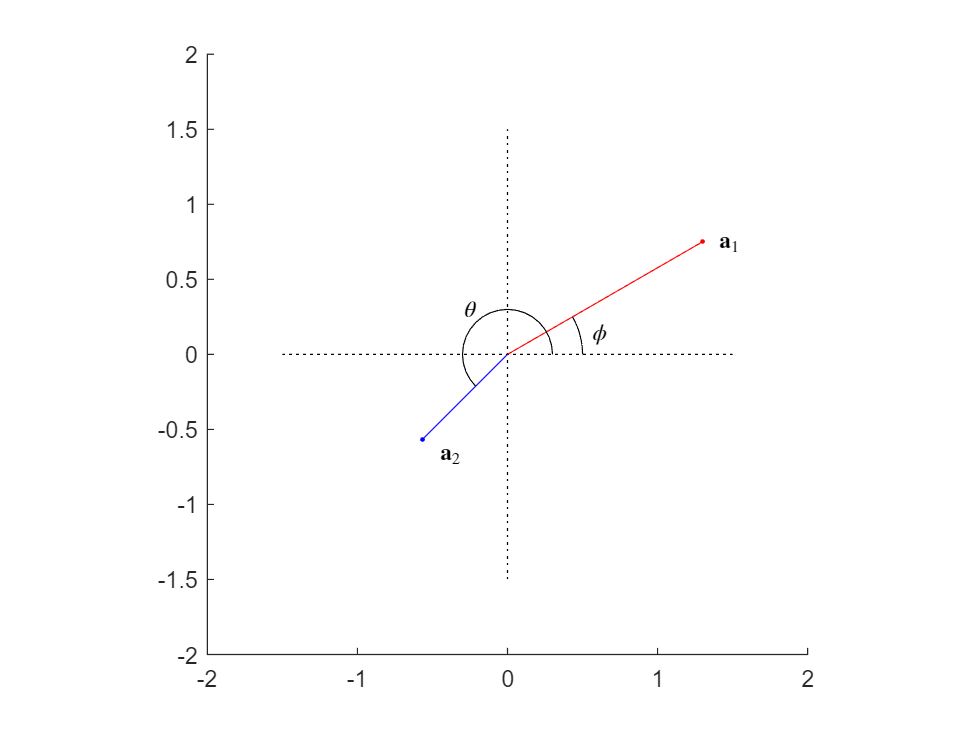

figII_1_1()

    
$$A^TA=\left[\matrix{\alpha\cos\theta & \alpha\sin\theta\cr \beta\cos\phi &\beta\sin\phi}\right]
\left[\matrix{\alpha\cos\theta & \beta\cos\phi \cr \alpha\sin\theta & \beta\cos\phi}\right]=
\left[\matrix{\alpha^2\cos^2\theta+\alpha^2\sin^2\theta & \alpha\beta\cos\theta\cos\phi+\alpha\beta\sin\theta\sin\phi\cr 
\alpha\beta\cos\theta\cos\phi+\alpha\beta\sin\theta\sin\phi & \beta^2\cos^2\phi+\beta^2\sin^2\phi
}\right]$$


Making use of the well-known trig identities, $\cos^2\psi+\sin^2\psi=1~\text{ and }~
\cos(\psi-\xi)=\cos(\psi)\cos(\xi)+\sin(\psi)\sin(\xi)$ we see

    $G=A^TA=\left[\matrix{\alpha^2 & \alpha\beta\cos(\theta-\phi)\cr \alpha\beta\cos(\theta-\phi) &\beta^2}\right]$.

The three values $\alpha^2,~\beta^2,~\alpha\beta\cos(\theta-\phi)$ defining $G$ have important geometric meaning:

- $\alpha^2={\bf a}_1\cdot{\bf a}_1$ is the square of the length of ${\bf a}_1$ (i.e., $||{\bf a}_1||=\alpha$),

- $\beta^2={\bf a}_2\cdot{\bf a}_2$ is the square of the length of ${\bf a}_2$ (i.e., $||{\bf a}_2||=\beta$),

- $\alpha\beta\cos(\theta-\phi)={\bf a}_1\cdot{\bf a}_2$ allows the deduction of the angle between the two vectors (i.e., $\theta-\phi=\arccos({\bf a}_1\cdot{\bf a}_2/(\alpha\beta))$).

Thus, we have all the geometric information concerning the relative positions of the two vectors in the Gram matrix.   Notice, that we cannot determine from the Gram matrix the angles, $\theta$ and $\phi$, that the vectors make with the $x-$axis of the coordinate system; this information has been lost in forming the Gram matrix.

Algebraically, a Gram matrix is ***positive semi-definite***.  A  $n\times n$ real symmetric matrix $G$ is ***positive semi-definite ***iff 

        (II.1.4)        ${\bf x}^T G {\bf x}\ge 0$        for all     ${\bf x}\in {\mathbb R}^n$.

It is easy to see that every Gram matrix is positive semi-definite.

                   ${\bf x}^T(A^TA){\bf x}=({\bf x}^T A^T)(A{\bf x})=(A{\bf x})^T(A{\bf x})=||A{\bf x}||^2\ge 0$.

If the inequality in (II.1.4) is replaced by strict inequality for ${\bf x}\ne {\bf 0}$, then the matrix is said to be ***positive definite.***   These consideration can be appropraitely extended to complex matrices where "real symmetric" is replaced by "Hermitian symmetric" and the Hermitian transpose is used.

**Matrices with orthonormal columns.**   If the Gram matrix of a matrix $A=\left[\matrix{{\bf a}_1 &\cdots &{\bf a}_n}\right]$ is the identity matrix ($A^TA=I$), then the length of each column is 1 and the angle between any two (different) columns is $\pi/2$ (i.e., the columns are mutually orthogonal).   When these conditions,

        (II.1.5)        $\matrix{
||{\bf a}_i|| =1 & \text{for} &i=1,\dots,n\cr
{\bf a}_i\cdot{\bf a}_j=0 &\text{for}&i\ne j}$,

are fulfilled the set of column vectors are ***orthonormal*** (both perpendicular to one another and each of unit length).    The vectors $\hat{\bf i}, \hat{\bf j}~\text{and}~\hat{\bf k}$, commonly used in the physical sciences, are the canonical example of an orthonormal set of vectors.    Similarly, the standard basis $\{{\bf e}_1,\dots,{\bf e}_n\}$is an orthonormal set of vectors in ${\mathbb R}^n.$   Some further examples:

format rat
A=[2/3 -2/3; 1/3 2/3; 2/3 1/3]

A =        2/3           -2/3     
       1/3            2/3     
       2/3            1/3     


A'*A

ans =        1              0       
       0              1       


format short
A=[1/sqrt(2) -1/sqrt(2); 1/sqrt(2) 1/sqrt(2)]

A =     0.7071   -0.7071
    0.7071    0.7071


A'*A

ans =     1.0000         0
         0    1.0000


format rat
A=[1/2 1/2 1/2; 1/2 -1/2 1/2; 1/2 1/2 -1/2; 1/2 -1/2 -1/2]

A =        1/2            1/2            1/2     
       1/2           -1/2            1/2     
       1/2            1/2           -1/2     
       1/2           -1/2           -1/2     


A'*A

ans =        1              0              0       
       0              1              0       
       0              0              1       


**Orthogonal matrices.**   A real square matrix that has the identity as its Gram matrix is known as an ***orthogonal ***matrix.   A matrix $A\in {\mathbb R}^{n\times n}$ is orthogonal if and only if

        (II.1.6)        $A^T A=I$.

Due to its significance, the set (family) of all $n\times n$ orthogonal matrices has the special designation $\text{O}(n)$.   A quick look at $\text{O}(2)$ gives some idea of why the orthogonal matrices are considered so important.   It turns out that $\text{O}(2)$ contains matrices of two kinds:   the rotations and the reflections.

$\text{Rot}(\theta)=\left[\matrix{ \cos\theta & -\sin\theta\cr \sin\theta & \cos\theta}\right]$        and        $\text{Ref}(\theta)=\left[\matrix{\cos2\theta & \sin2\theta \cr \sin2\theta &-\cos2\theta}\right]$

It is easily checked that these matrices are square and have the identity as their Gram matrix.


$$\left[\matrix{ \cos\theta & \sin\theta\cr -\sin\theta & \cos\theta}\right]\left[\matrix{ \cos\theta & -\sin\theta\cr \sin\theta & \cos\theta}\right]=\left[\matrix{\cos^2\theta+\sin^2\theta & -\cos\theta\sin\theta+\sin\theta\cos\theta\cr
 -\cos\theta\sin\theta+\sin\theta\cos\theta & \cos^2\theta+\sin^2\theta
}\right]=\left[\matrix{1&0\cr0&1}\right]$$



$$\left[\matrix{\cos2\theta & \sin2\theta \cr \sin2\theta &-\cos2\theta}\right]\left[\matrix{\cos2\theta & \sin2\theta \cr \sin2\theta &-\cos2\theta}\right]=\left[\matrix{\cos^22\theta+\sin^2 2\theta & \cos2\theta\sin2\theta-\cos2\theta\sin2\theta\cr 
 \cos2\theta\sin2\theta-\cos2\theta\sin2\theta & \cos^22\theta+\sin^2 2\theta }\right]=\left[\matrix{1&0\cr0&1}\right]$$


The reason for the names for these two kinds of matrices can be seen from the geometric properties of the linear maps they represent:

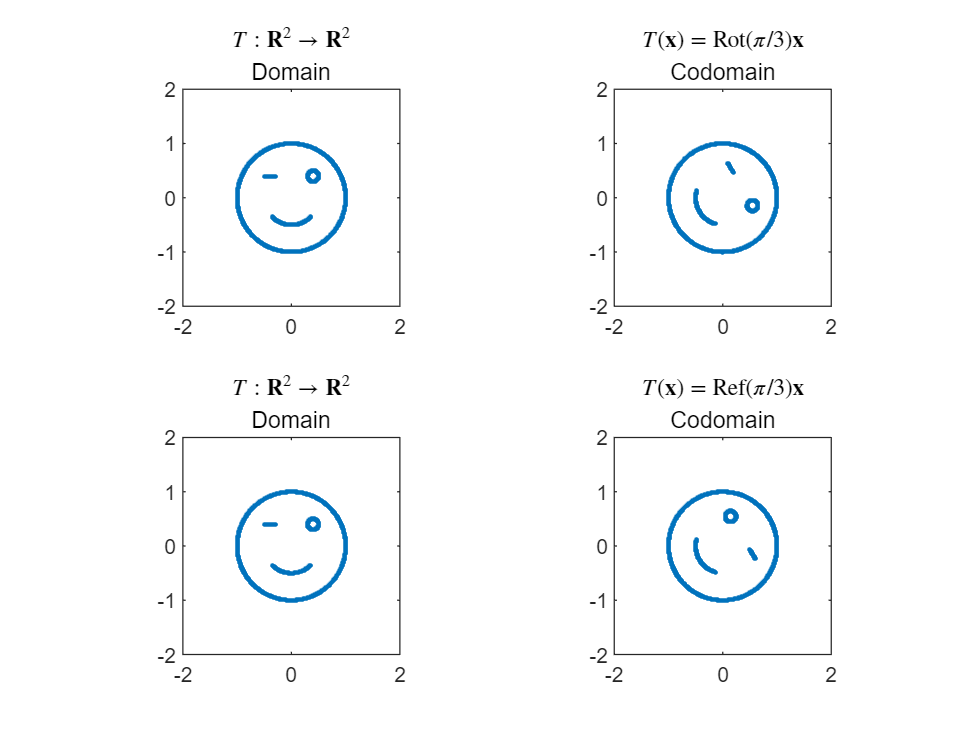

figII_1_2()

Notice both transforms do not distort the faces in the sense that distances between features are unchanged.   However, one of the transforms does change the orientation of the face (i.e., left becomes right and vice versa).

**Inverse of an orthogonal matrix.**   The defining characteristic of an orthogonal matrix $A$, namely $A^TA=I$, informs us that $A^T$is a left inverse for $A$.   We know that if there is also a right inverse for $A$it will be equal to the left inverse, but we have not yet argued that a left inverse matrix guarantees existence of a right inverse.    We now demonstrate that a left inverse for a square matrix provides a way to construct a right inverse:  

- To find $B$ with the property $\textrm{AB}=I$it suffices to find solutions to $A{\bf b}_\ell={\bf e}_\ell$ for $\ell=1,\dots,n$.  But solutions for these matrix equations are easily found by multiplying these equations on the left by the postulated left inverse (here $A^T$).  So, $A^TA{\bf b}_\ell=A^T{\bf e}_\ell$ implying ${\bf b}_\ell=A^T{\bf e}_\ell$.   That is, ${\bf b}_\ell$ is the $\ell^{\text{th}}$ column of left inverse $A^T$.   So indeed, the right inverse exists and is equal to the left inverse.

Hence, every orthogonal matrix has an inverse which is equal to its transpose.   In symbols, $\text{O}(n)\subset \text{GL}(n)$ and $A\in \text{O}(n)~\Rightarrow~A^{-1}=A^T$.    From a computational perspective, computing the inverse of an orthogonal matrix (which requires no arithmetic) is far easier than computing the inverse of a general nonsingular matrix.

$\text{O}(n)$ **is closed under matrix multiplication.**    We show that the product of two orthogonal matrices is also orthogonal.    

- Suppose that $A$and $B$ are $n\times n$ orthogonal matrices (i.e., $A^TA=B^T B=I$).    We want to see that $(AB)^T(AB)=I.$   Indeed, $(AB)^T(AB)=(B^TA^T)(AB)=B^T(A^TA)B=B^TIB=B^TB=I$.

Hence, $\text{O}(n)$ is closed under matrix multiplication (as well as matrix inversion).   

**Permutation matrices.**   An $n\times n$ matrix formed by reordering the rows (or columns) of the identity matrix is known as a ***permutation ***matrix.  We denote the set of all $n\times n$ permutation matrices $S_n$.    Every permutation matrix is an orthogonal matrix.

        $S_2=\left\{ \left[\matrix{ 1 & 0 \cr 0 & 1 }\right],~
\left[\matrix{ 0 & 1 \cr 1 & 0 }\right]\right\}$,        $S_3=\left\{
\left[\matrix{1&0&0\cr0&1&0\cr0&0&1}\right],~ 
\left[\matrix{0&1&0\cr1&0&0\cr0&0&1}\right],~
\left[\matrix{0&0&1\cr0&1&0\cr1&0&0}\right],~
\left[\matrix{1&0&0\cr0&0&1\cr0&1&0}\right],~
\left[\matrix{0&1&0\cr0&0&1\cr1&0&0}\right],~
\left[\matrix{0&0&1\cr1&0&0\cr0&1&0}\right]\right\}
$.

The set $S_n$ contains $n!$ elements.    The product of permutation matrices is a permutation matrix.

**Unitary matrices.**   An $n\times n$ matrix $A$ (which may have complex entries) is ***unitary*** if and only $A^HA=I$.   The set of all $n\times n$ unitary matrices is denoted $\text{U}(n)$.  Because orthogonal matrices are defined to have real entries and the Hermitian transpose equals the ordinary transpose for real matrices, we see that every orthogonal matrix is unitary (i.e., $\text{O}(n)\subset\text{U}(n)$).

format short 
A=[9+12i -12-16i; 12+16i 9+12i]/25

A =    0.3600 + 0.4800i  -0.4800 - 0.6400i
   0.4800 + 0.6400i   0.3600 + 0.4800i


A'*A

ans =    1.0000 + 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


The properties of unitary matrices are mostly analogous to the properties of orthogonal matrices; hence, the emphasis of our study is on orthogonal matrices.   However, in applications where complex matrices arise naturally, unitary matrices often play a vital role.

**Projection matrices.   **Although projection matrices have very significant geometric properties, we focus here on a purely algebraic perspective.   A square matrix $P$ is a projection matrix if and only if

        (II.1.7)        $P^2=P$.   

This property assures that not only the square of $P$ but $P$ raised on the power of any positive integer equals $P$, i.e., $P^\ell=P\quad\text{for}\quad \ell=1,2,3,\dots$.   For example, $P^3=PP^2=PP=P^2=P.$   In fact (II.1.7) indicates that $P$ is its own square root suggesting the correct equation $P^{\frac12}=P.$   While we save some of the details until later lessons, it is indeed true that

        (II.1.8)        $P^\alpha=P\quad\text{for}\quad \alpha>0$.

The extreme examples of $n\times n$ projection matrices are the zero matrix $O$ and the identity matrix $I$.   Notice that both obviously satisfy (II.1.6).    For $n>1$ there are many more including the rank 1 projections which have the form

        (II.1.9)        $P={\bf u}{\bf v}^H$     where     ${\bf u}\cdot{\bf v}={\bf u}^H{\bf v}=1$.

In this case we easily check (II.2.6):  $P^2=({\bf u}{\bf v}^H)({\bf u}{\bf v}^H)={\bf u}( {\bf v}^H{\bf u}){\bf v}^H={\bf u}( {\bf u}^H{\bf v})^H{\bf v}^H={\bf u}{\bf v}^H=P$.

**Orthogonal projection matrices.**   Projection matrices that are real symmetric matrices ($P^T=P$) are known as orthogonal projection matrices.   The rank 1 projection matrices given by (II.1.8) will be symmetric if ${\bf v}={\bf u}$ since $\left({\bf u}{\bf u}^H\right)^H={\bf u}{\bf u}^H$.  In this case, we see that ${\bf u}$ is a unit vector as ${\bf u}\cdot{\bf u}=||{\bf u}||^2=1$.   A particular property of an orthogonal projection matrix $P$ is that it decomposes any compatible vector ${\bf x}$ into two orthogonal components:

        (II.1.10)        ${\bf x}_{||}=P{\bf x}\qquad\text{and} \qquad{\bf x}_\perp={\bf x}-P{\bf x}$.

It is easy to verify the two key properties of these two vectors:

    
$${\bf x}_{||}~+~{\bf x}_\perp~=~P{\bf x}~+~{\bf x}-P{\bf x}~=~{\bf x}$$


    
$${\bf x}_{||}\cdot{\bf x}_\perp~=~(P{\bf x})\cdot({\bf x}-P{\bf x})~=~(P{\bf x})^H{\bf x}-(P{\bf x})^HP{\bf x}~=~{\bf x}^HP^H{\bf x}-{\bf x}^HP^HP{\bf x}~=~{\bf x}^HP{\bf x}-{\bf x}^HP^2{\bf x}~=~{\bf x}^HP{\bf x}-{\bf x}^HP{\bf x}~=~0$$


In later lessons, we further pursue the geometric nature of projections in some depth.   Here a simple diagram showing the decomposition of a vector into two orthogonal components is provided.

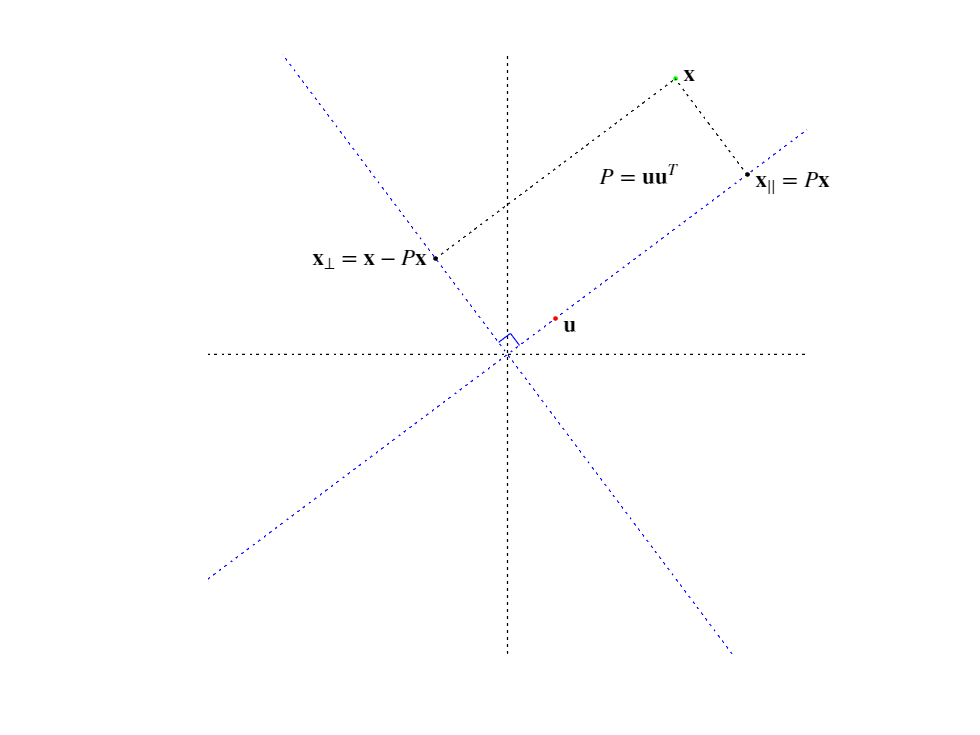

figII_1_3()

**Stochastic matrices.    **A matrix in ${\mathbb R}^{n\times n}$ having nonnegative entries and having sum of the entries in each column equal to 1 is known as a ***stochastic*** or ***Markov*** matrix.    Some examples of stochastic matrices:

                $\left[\matrix{
\frac19 & \frac17 & \frac15 \cr
\frac49 & \frac37 & \frac25 \cr
\frac49 &\frac37 & \frac25 
}\right], \qquad
\left[\matrix{
\frac12 & 1 & 0 & \frac13\cr
\frac14 & 0 & \frac13 & \frac14 \cr
\frac18 & 0 & \frac23 & \frac15 \cr
\frac18 & 0 & 0 & \frac{13}{60} \cr}\right],\qquad
\left[\matrix{\frac13&\frac19&\frac59\cr \frac49&\frac29&\frac13 \cr \frac29&\frac23&\frac19}\right]$.

Stochastic matrices are central to the study of Markov chains.   Stochastic matrices have two interesting closure properties.

- A convex combination (an affine combination with nonnegative coefficients) of stochastic matrices is a stochastic matrix.

- The product of stochastic matrices is stochastic.

**Follow-up Problems:**

**Problem II.1.1:  **For each pair of families of matrices in the bulleted list at the beginning of this lesson determine which, if either, is a subset of the other.

**Problem II.1.2:  **For each family of matrices in the bulleted list at the beginning of this lesson determine if the family is closed under (a) linear combination, (b) affine combination, (c) multiplication, (d) inversion, (e) Hermitian transpose.

**Problem II.1.3:   **A family of matrices is not closed under a certain operation if application of that operation to members of the set may produce something outside that set.    The set generated is the set produced by repeated application of an operation to members of some original set.    For example, we have seen that $\text{GL}_n$ is generated by applying matrix multiplication to the set of elementary matrices (i.e., every nonsingular matrix is a product of elementary matrices).    What is the set generated by applying matrix multiplication to the set of $3\times 3$ exchange matrices:


$$\left\{
\left[\matrix{0&1&0\cr1&0&0\cr0&0&1}\right],\quad
\left[\matrix{0&0&1\cr0&1&0\cr1&0&0}\right],\quad
\left[\matrix{1&0&0\cr0&0&1\cr0&1&0}\right]\right\}$$


**Problem II.1.4a:  **Compute the Gram matrix of each of the following.


$$\text{(a)}\quad \left[\matrix{1 & 2\cr 3 & 4 \cr 5 & 6}\right]\qquad
\text{(b)}\quad\left[\matrix{1 & 3 & 5\cr 2 &4 & 6}\right]\qquad
\text{(c)}\quad\left[\matrix{1\cr 2\cr 3}\right]\qquad
\text{(d)}\quad\left[\matrix{1 &2&3}\right]\qquad
\text{(e)}\quad
\left[\matrix{
\frac12 & \frac12 & \frac12 & \frac12 \cr
\frac12 & \frac12 & -\frac12 & -\frac12 \cr
\frac12 & -\frac12 & -\frac12 & \frac12 \cr
\frac12 & -\frac12 & \frac12 & -\frac12 \cr}\right]$$


**Problem II.1.4b:**   Find, if possible, a real upper triangular matrix with positive entries on the diagonal for which each given matrix is the Gram matrices.

 (a)    $\left[\matrix{1 & 2 \cr 2 & 13}\right]$        (b)    $\left[\matrix{1 & 1 \cr 1 &1}\right]$        (c)     $\left[\matrix{1 & 2 \cr 2 &1}\right]$        (d)     $\left[\matrix{2 & 1 \cr 1 &2}\right]$

**Problem II.1.5:  **Verify the following formulas:


$$\text{Rot}(\theta)\text{Rot}(\phi)=\text{Rot}(\theta+\phi)\qquad\qquad\qquad
\text{Ref}(\theta)\text{Ref}(\phi)=\text{Rot}(2\theta-2\phi)$$



$$\text{Rot}(\theta)\text{Ref}(\phi)=\text{Ref}(\phi+\frac12\theta)\qquad\qquad\qquad
\text{Ref}(\theta)\text{Ref}(\phi)=\text{Rot}(\theta-\frac12\phi)$$


Remarkably, the last formula shows that every rotation is the product of two reflections which is true even if we require $\phi=0$.

**Problem II.1.6:   **Suppose that $A\in\text{O}(n)$ and ${\bf x}_1~\text{and}~ {\bf x}_2$ are vectors in ${\mathbb R}^n$.   Let ${\bf y}_1=A{\bf x}_1$ and ${\bf y}_2=A{\bf x}_2$.  Show

$||{\bf x}_1-{\bf x}_2||=||{\bf y}_1-{\bf y}_2||$.

Because the distance between the points in the domain and the distance between their images in the codomain are equal, transformations defined by an orthogonal matrix are called ***isometries.***

**Problem II.1.7:  **Compute $\left[\matrix{0 & 1 & 0 \cr 0 & 0 & 1 \cr 1 & 0 & 0 }\right] \left[\matrix{
a_1 & b_1 & c_1 & d_1\cr
a_2 & b_2 & c_2 & d_2\cr
a_3 & b_3 & c_3 & d_3}\right].$  Describe the action of a permutation matrix multiplied on the left of compatible matrix.

**Problem II.1.8:**  Suppose ${\bf v}$ is a unit vector.   Show that $A=I-2{\bf v}{\bf v}^H$ is a unitary matrix.

**Problem II.1.9:   **Which of the following matrices are projection matrices?


$$\text{(a)}\quad\left[\matrix{1 &0&0\cr0&1&0\cr0&0&0}\right]\qquad
\text{(b)}\quad\left[\matrix{1 & 0 & 0\cr0 & 0 & 0 \cr0 & 0 & 1}\right]\qquad
\text{(c)}\quad\left[\matrix{1 & 0 & 0\cr 0 & 0 & 1 \cr 0 & 1 & 0}\right]\qquad
\text{(d)}\quad\left[\matrix{\frac12 & 0 & \frac12\cr 0 & 1 & 0\cr \frac12 & 0 & \frac12}\right]\qquad
\text{(e)}\quad\left[\matrix{\frac13&\frac13&\frac13\cr\frac13&\frac13&\frac13\cr\frac13&\frac13&\frac13}\right]$$


**Problem II.1.10:   **Suppose that $P$ is a projection matrix and $Q=I-P\ldotp$  Show that (a)  $Q$ is a projection matrix, (b) $\textrm{PQ}=\textrm{QP}$ is a zero matrix , and (c) $P+Q=I$ is the identity matrix.   

**Problem II.1.11:**   Suppose $\{{\bf u}_1,\dots,{\bf u}_p\}\subset{\mathbb R}^n$ is an orthonormal set.   Show that $Q={\bf u}_1{\bf u}_1^H~+~\cdots~+~{\bf u}_p{\bf u}_p^H$ is an orthogonal projection.

**Problem II.1.12:   **Show that the product of stochastic matrices is a stochastic matrix.

**Problem II.1.13:  **The definition of positive semi-definite matrix given in the lesson was provided only for real symmetric matrices.   Yet the condition ${\bf x}^T A {\bf x}\ge 0$ can easily be applied to any square real matrix.    A likely reason for limiting the definition to real symmetic matrices is that for real square matrice the question of whether or not ${\bf x}^T A {\bf x}\ge 0$ depends only on the symmetric part of $A$:

$\frac12(A+A^T)$.

Show (a) the symmetric part of a square real matrix is indeed a symmetric matrix, (b) that ${\bf x}^T A {\bf x}\ge 0$ if and only if ${\bf x}^T\frac12(A+A^T){\bf x}\ge0$ and (c) every real square matrix $A$ is the sum of its symmetric part and its antisymmetric part:  $\frac12(A-A^T)$.

**Problem II.1.14:  **How can the concept of positive semi-definite matrices be extended to complex matrices (in a way that does not change the definition for real matrices).

function figII_1_1()
axis([-2 2 -2 2])
axis square
hold on
plot([-1.5 1.5],[0 0],':k')
plot([0 0],[-1.5 1.5],':k')
theta=pi/6;
a1=1.5*[cos(theta); sin(theta)];
phi=5*pi/4;
a2=0.8*[cos(phi); sin(phi)];
plot(a1(1),a1(2),'.r')
plot([0 a1(1)],[0 a1(2)],'r')
text(a1(1)+0.1,a1(2),'${\bf a}_1$','interpreter','latex')
plot(a2(1),a2(2),'.b')
plot([0 a2(1)],[0 a2(2)],'b')
text(a2(1)+0.1,a2(2)-0.1,'${\bf a}_2$','interpreter','latex')
plot(0.3*cos(0:phi/20:phi),0.3*sin(0:phi/20:phi),'k')
text(0.55,0.15,'$\phi$','interpreter','latex')
plot(0.5*cos(0:theta/20:theta),0.5*sin(0:theta/20:theta),'k')
text(-0.3,0.3,'$\theta$','interpreter','latex')
end

function figII_1_2()
%%%%%% Make a face
theta=0.0:0.01:2*pi; 
outline = [ cos(theta); sin(theta)];                     % outline of face 
leye    = [0.4+0.1*cos(theta);0.4+0.1*sin(theta)];       % left eye
reye    = [-0.5:0.01:-0.3; 0.4*(1+0*(-0.5:0.01:-0.3))];  % right eye
theta   = 5*pi/4:0.01:7*pi/4;
smile   = [0.5*cos(theta); 0.5*sin(theta)];              % smile
face    = [outline leye reye smile];                     % face assembled
%%%%%% Standard matrix for a clockwise rotation by pi/3
theta = pi/3;
A = [cos(theta) sin(theta); -sin(theta) cos(theta)];
Tface = A*face;
%%%%%% Plotting 
subplot(2,2,1)
plot(face(1,:),face(2,:),'.')
axis equal
axis([-2 2 -2 2])
title('$T:{\bf R}^2\to{\bf R}^2$','Interpreter','latex')
subtitle('Domain')
subplot(2,2,2)
plot(Tface(1,:),Tface(2,:),'.')
axis equal
axis([-2 2 -2 2])
title('$T({\bf x})=$Rot$(\pi/3){\bf x}$','Interpreter','latex')
subtitle('Codomain')
%%%%%% Standard matrix for a clockwise rotation by pi/3
theta = pi/3;
A = [cos(2*theta) sin(2*theta); sin(2*theta) -cos(2*theta)];
Tface = A*face;
%%%%%% Plotting 
subplot(2,2,3)
plot(face(1,:),face(2,:),'.')
axis equal
axis([-2 2 -2 2])
title('$T:{\bf R}^2\to{\bf R}^2$','Interpreter','latex')
subtitle('Domain')
subplot(2,2,4)
plot(Tface(1,:),Tface(2,:),'.')
axis equal
axis([-2 2 -2 2])
title('$T({\bf x})=$Ref$(\pi/3){\bf x}$','Interpreter','latex')
subtitle('Codomain')
end

function figII_1_3()
figure
hold on
axis([-5 5 -5 5])
axis off
axis equal
plot([-5 5],[0 0],':k')
plot([0 0],[-5 5],':k')
plot([-5 5],[-15/4 15/4],':b')
plot([15/4 -15/4],[-5 5],':b')
plot([1/5 1/20],[3/20 7/20],'b')
plot([-3/20 1/20],[1/5 7/20],'b')
plot(4/5,3/5,'.r')
text(4/5+0.1,3/5-0.1,'${\bf u}$','Interpreter','latex')
plot(14/5,23/5,'.g')
text(14/5+0.1,23/5+0.1,'${\bf x}$','Interpreter','latex')
plot(4,3,'.k')
text(4+0.1,3-0.1,'${\bf x}_{||}=P{\bf x}$','Interpreter','latex')
plot(-6/5,8/5,'.k')
text(-6/5-2.1,8/5,'${\bf x}_\perp={\bf x}-P{\bf x}$','Interpreter','latex')
plot([-6/5 14/5],[8/5 23/5],':k')
plot([4 14/5],[3 23/5],':k')
text(1.5,3,'$P={\bf u}{\bf u}^T$','Interpreter','latex')
end